# Tutorial on the calculations of time-varying *instantaneous * and *cumulative *Information about stimulus in spike patterns

In this tutorial, we are generating a model neuron responses to hypothetical stimuli in order to demonstrate how to calculate time varying information using the code described in Elie and Theunissen 2018.

The first step consists in obtaining spike pattern responses modeled as inhomogenous Poisson processes. The time varying rates of the artificial neuron in response to 4 hypothetical stimuli is arbitrary fixed. Then these rates are used as the lambdas of inhomogenous Poisson distributions to generate 10 realizations per stimulus.

The second step corresponds to the estimation of the time varying rates by applying the kernel density estimation algorithm written by Hideaki Shimazaki and Shigeru Shinomoto on the realizations generated at step 1. A Jackknife procedure is used to estimate the error on the rate calculation.

The third step consists in binning the obtained time varying rates at 100Hz and calculate the *instantaneous* information in the neural response about the stimulus at each time bin. The error on the calculation due to the uncertainty of the exact time varying spike rates is estimated by a bootstrap and a Jackknife procedure.

The fourth and final step uses the probability distribution of conditional responses generated at step 3 to calculate the *cumulative* information about the stimulus at each time bin using a Monte Carlo with importance sampling approach. The error on the calculation due to the uncertainty of the exact time varying spike rates and to the stochastic aspect of the sampling approach is estimated by a bootstrap and a Jackknife procedure.

This tutorial requires the code for calculating kernel density estimates of the spike patterns, ssvkernel, written by Hideaki Shimazaki and Shigeru Shinomoto  and available here:

[https://github.com/shimazaki/density_estimation](https://github.com/shimazaki/density_estimation)

Several plots call the function shaddedErrorBar written by Rob Campbell and available there:

[https://github.com/raacampbell/shadedErrorBar](https://github.com/raacampbell/shadedErrorBar)

% Cell name: Change the cell name if you want to run again this script and get your own version
Cell = 'ModelCell';

% Set up paths (were assume that you run this tutorial from the cloned repository PoissonTimeVaryingInfo
Path2Data = pwd;
addpath(genpath(Path2Data))
% Set up the extra-required paths assuming you placed this dependent repositories at the same level as PoissonTimeVaryingInfo
[Path2Code,~]=fileparts(Path2Data);
addpath(genpath(fullfile(Path2Code, 'density_estimation')))
addpath(genpath(fullfile(Path2Code, 'shadedErrorBar')))

## 1.Obtaining 10 realizations of neural responses modeled as inhomogenous Poisson processes for 4 hypothetical stimuli

Here besides gathering the 10 realizations for each stimulus, we are also grouping the realizations into 10 groups of 9 realizations for the Jackknife procedure.

fprintf('**************** Obtaining spike trains *****************\n******** from inhomogenous Poisson spike counts ***********\n*********************************************************');

**************** Obtaining spike trains *****************
******** from inhomogenous Poisson spike counts ***********
*********************************************************

% The following lines generate the lambda of the inhomogenous Poisson rate for 4 stimuli
NR_Duration=400; % Duration of the spike patterns set to be 400ms
Response_samprate = 1000; % Response sampling rate set to be 1kHz
NStims=4; % 4 stimuli
Step=10; % bin size in ms at which the ground truth Poisson rate is given
Win = Step:Step:NR_Duration;
Nb_Win = length(Win);
BackRate = 0.1;
Input_Spike_count.stim1 = ones(1,Nb_Win)*BackRate;
Input_Spike_count.stim1(4:8)=[1.5 2.5 2.5 1.5 0.5];

Input_Spike_count.stim2 = ones(1,Nb_Win)*BackRate;
Input_Spike_count.stim2(13:17) = [1.5 2.5 1.5 1.5 0.5];

Input_Spike_count.stim3 = ones(1,Nb_Win)*BackRate;
Input_Spike_count.stim3(22:26) = [1 1.5 1.5 1 0.5];

Input_Spike_count.stim4 = ones(1,Nb_Win)*BackRate;
Input_Spike_count.stim4(32:36)=[1 1.5 2.5 1.5 0.5];

% Then we generate spike trains (10 per stim) with inhomogenous Poisson distribution
NTrials=10;
DataCell.Spike_array = struct(); % contains the array of spikes for each stim (number of spikes in each 1ms bin for each trial)
DataCell.Input_Spike_count = nan(NStims, Nb_Win); % Ground truth Poisson rate: contains the time varying spike rate (# spikes /Step ms window) for each stim that is used as an input mean to the inhomogenous Poisson responses
DataCell.NSpikes = struct(); % contains the total sum number of spikes for each stimulus accross the NTrials trials (one scalar per stimulus)
DataCell.JK_NSpikes = struct(); % contains the total sum number of spikes for each stimulus and each Jackknife accross (NTrials-1) trials (one vector per stimulus)
DataCell.Spike_arrival = struct(); % contains all spike arrival times from all trials for each stim (one vector per stimulus)
DataCell.JK_Spike_arrival = struct(); % contains all spike arrival times from (NTrials-1) trials of the NTrials Jackknife sets of trials for each stimulus (one NTrials cell per stimulus where each cell is a vector of arrival times)


for stim=1:NStims
    DataCell.Spike_array.(sprintf('stim%d',stim))= zeros(NTrials,NR_Duration*Response_samprate/1000);
    DataCell.Input_Spike_count(stim,:) = Input_Spike_count.(sprintf('stim%d',stim));
    NSpikeslocal = nan(NTrials,1);
    
    for tt=1:NTrials
        NbSpikes_temp = poissrnd(Input_Spike_count.(sprintf('stim%d',stim)));
        NSpikeslocal(tt) = sum(NbSpikes_temp);
        Win_old=0;
        for ww=1:(Nb_Win-1)
            if NbSpikes_temp(ww)>0
                Ind=[];
                NS_temp = NbSpikes_temp(ww);
                while NS_temp>0
                    Ind = [Ind randperm(Step*Response_samprate/1000,min(Step*Response_samprate/1000,NS_temp))];
                    NS_temp = NS_temp - min(Step*Response_samprate/1000,NS_temp);
                end
                for ii=1:NbSpikes_temp(ww)
                    DataCell.Spike_array.(sprintf('stim%d',stim))(tt,Win_old*Response_samprate/1000+Ind(ii)) = DataCell.Spike_array.(sprintf('stim%d',stim))(tt,Win_old*Response_samprate/1000+Ind(ii)) + 1;
                end
            end
            Win_old=Win(ww);
        end
    end
    
    % Total number of spikes over all trials of that stim
    DataCell.NSpikes.(sprintf('stim%d',stim)) =  sum(NSpikeslocal);
    
    
    % Initializing the variable that will contain Total number of spikes over all (NTrials-1) trials of that stim JK sets
    DataCell.JK_NSpikes.(sprintf('stim%d',stim)) = nan(NTrials,1);
    
    % Getting spike arrival times of all trials for that stim and for the NTrials JK estimations
    DataCell.Spike_arrival.(sprintf('stim%d',stim)) = nan(sum(NSpikeslocal),1);
    DataCell.JK_Spike_arrival.(sprintf('stim%d',stim)) = cell(NTrials,1);
    
    spike_count = 0;
    for tt=1:NTrials
        % Find the spike arival times for that trial and fill in the all-trial set of spike arrival time
        TA = find(DataCell.Spike_array.(sprintf('stim%d',stim))(tt,:));
        for sp=1:length(TA)
            Ns_local = DataCell.Spike_array.(sprintf('stim%d',stim))(tt,TA(sp));
            while Ns_local>0
                spike_count = spike_count +1;
                DataCell.Spike_arrival.(sprintf('stim%d',stim))(spike_count) = TA(sp)*1000/Response_samprate;
                Ns_local = Ns_local - 1;
            end
        end
        
        % suppress the spike arival times for that trial and fill in the (all-1) trial set of spike arrival time with the spike AT from all other trials
        NSpikeslocolocal = NSpikeslocal;
        NSpikeslocolocal(tt) = [];
        Localtrials = 1:NTrials;
        Localtrials(tt) = [];
        DataCell.JK_NSpikes.(sprintf('stim%d',stim))(tt) = sum(NSpikeslocolocal);
        DataCell.JK_Spike_arrival.(sprintf('stim%d',stim)){tt} = nan(sum(NSpikeslocolocal),1);
        spike_count_JK = 0;
        for tt2=1:(NTrials-1)
            tt3 = Localtrials(tt2);
            % Find the spike arival times for that trial and fill in the (all-1)-trial set of spike arrival time
            TA_JK = find(DataCell.Spike_array.(sprintf('stim%d',stim))(tt3,:));
            for sp=1:length(TA_JK)
                Ns_local = DataCell.Spike_array.(sprintf('stim%d',stim))(tt3,TA_JK(sp));
                while Ns_local>0
                    spike_count_JK = spike_count_JK +1;
                    DataCell.JK_Spike_arrival.(sprintf('stim%d',stim)){tt}(spike_count_JK) = TA_JK(sp)*1000/Response_samprate;
                    Ns_local = Ns_local - 1;
                end
            end
        end
    end
end   
DataCell.Win = Win;
DataCell.Step = Step;
DataCell.Response_samprate = Response_samprate;
DataCell.NR_Duration = NR_Duration;
DataCell.NTrials = NTrials;
DataCell.NStims = NStims;

% save the data to easily retrieve the same set later
save(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)),'-struct','DataCell');
fprintf('Data saved to %s',fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));

Data saved to /Users/elie/Documents/CODE/PoissonTimeVaryingInfo/ModelCell_InfoCumInfo_Tutorial.mat

fprintf('Each set of responses to a given stimulus contains %d responses of %d ms\n', NTrials, size(DataCell.Spike_array.stim1,2));  

Each set of responses to a given stimulus contains 10 responses of 400 ms


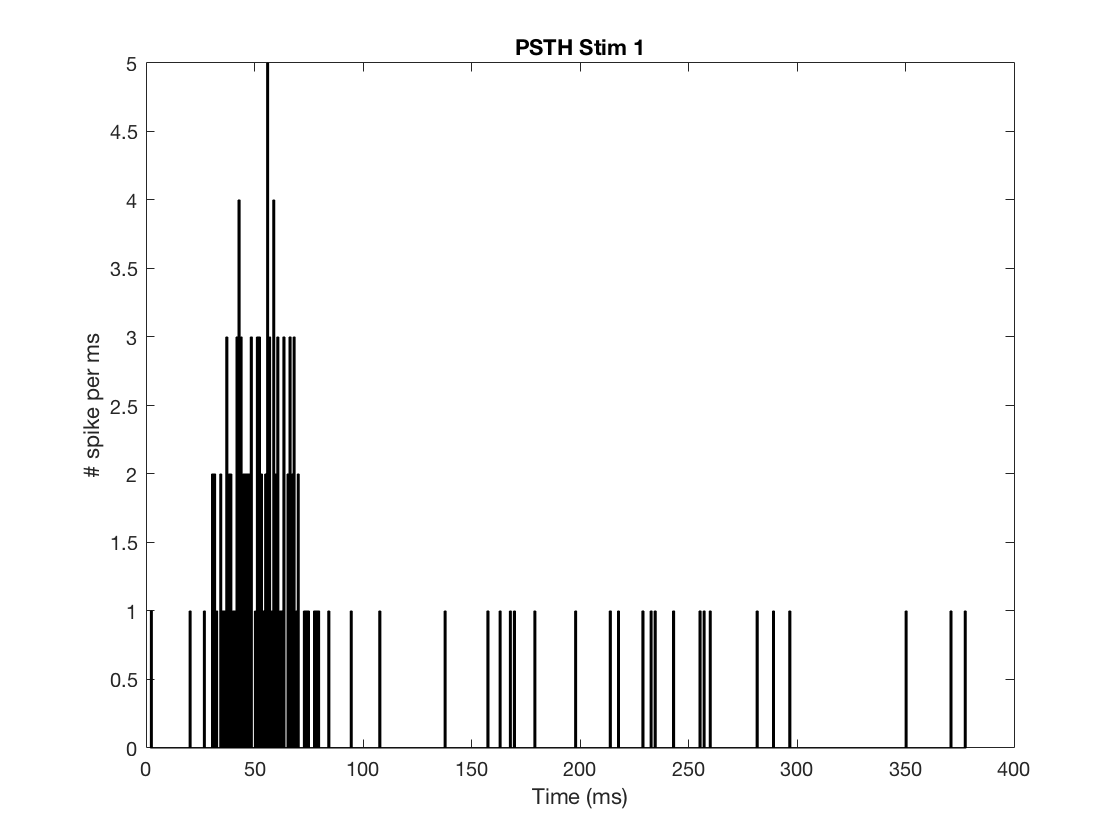

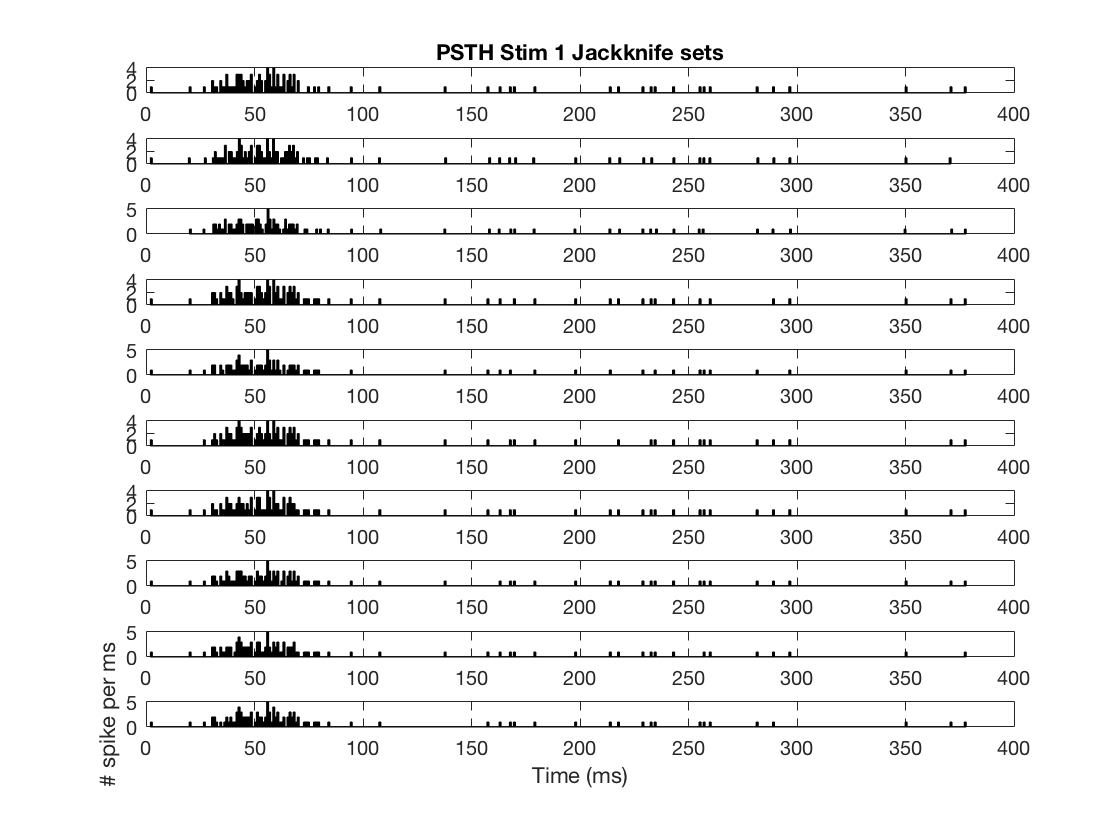

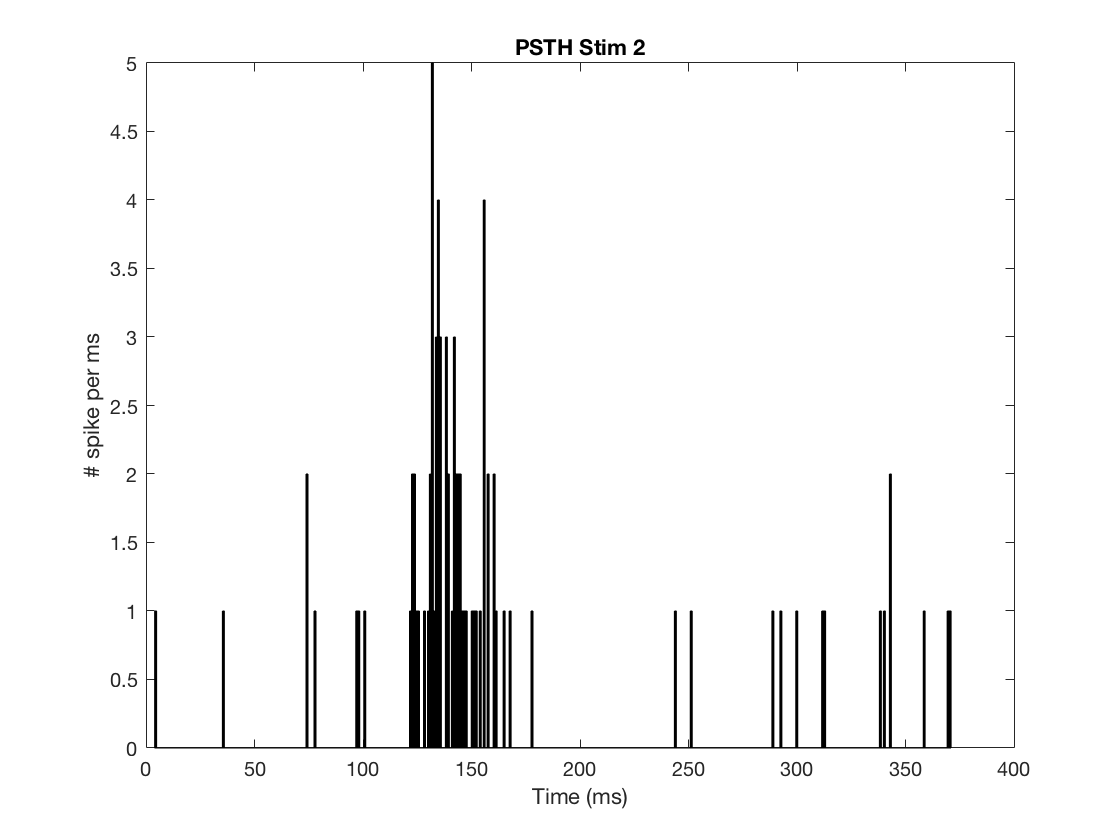

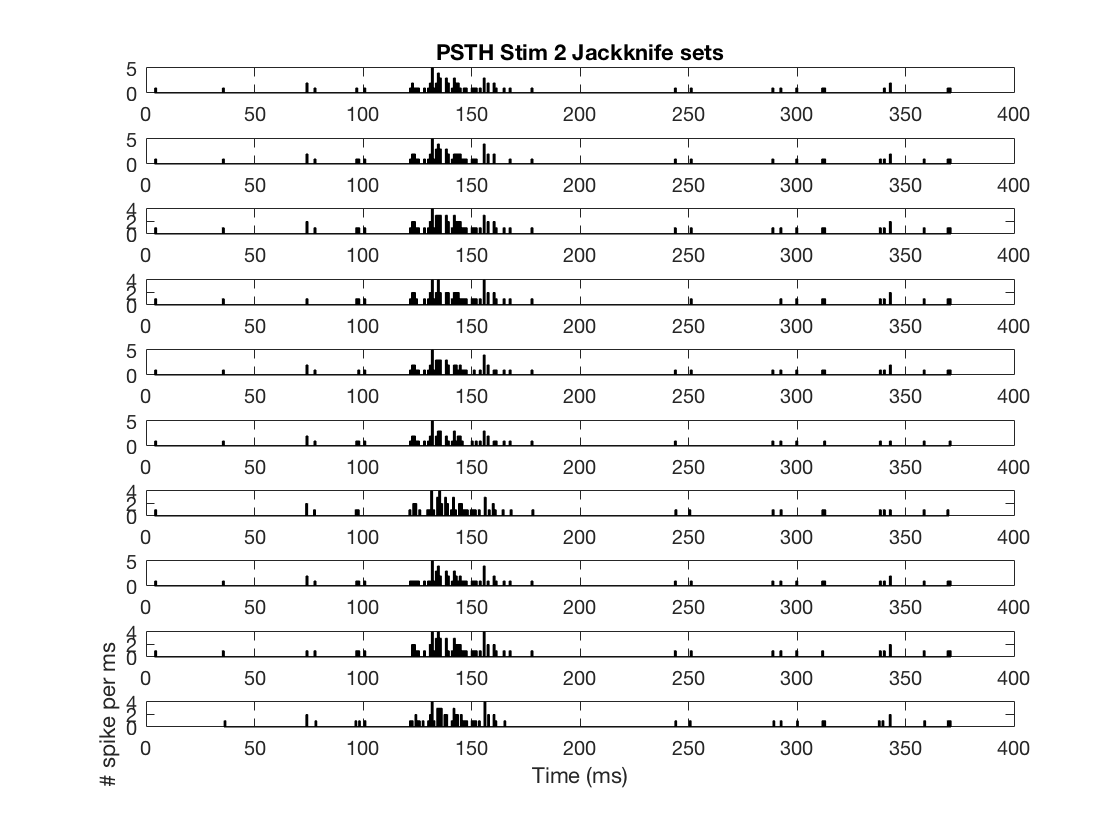

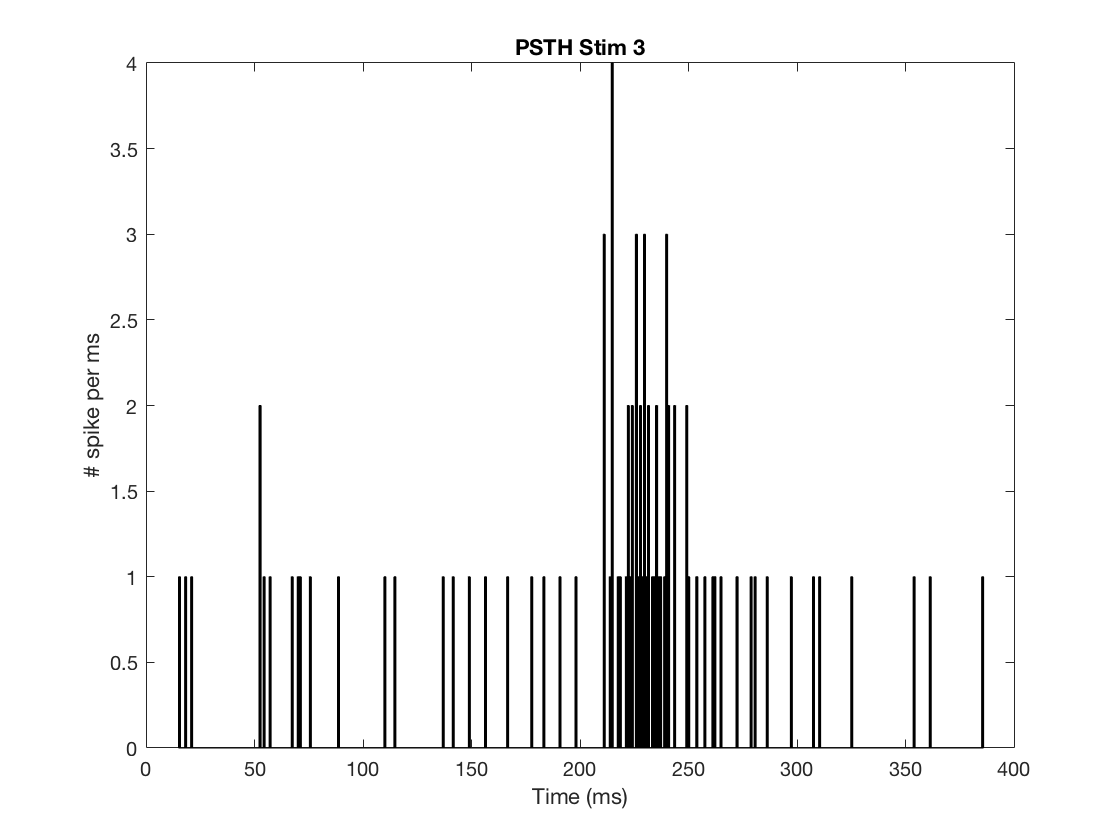

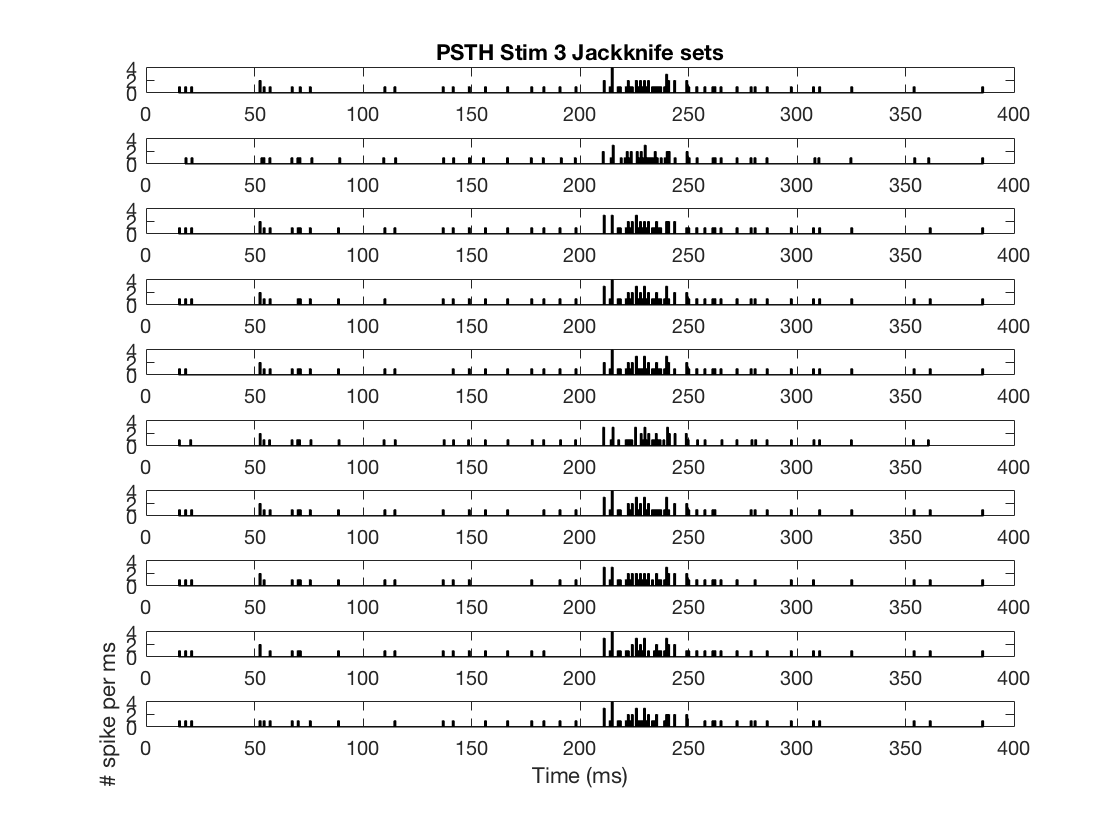

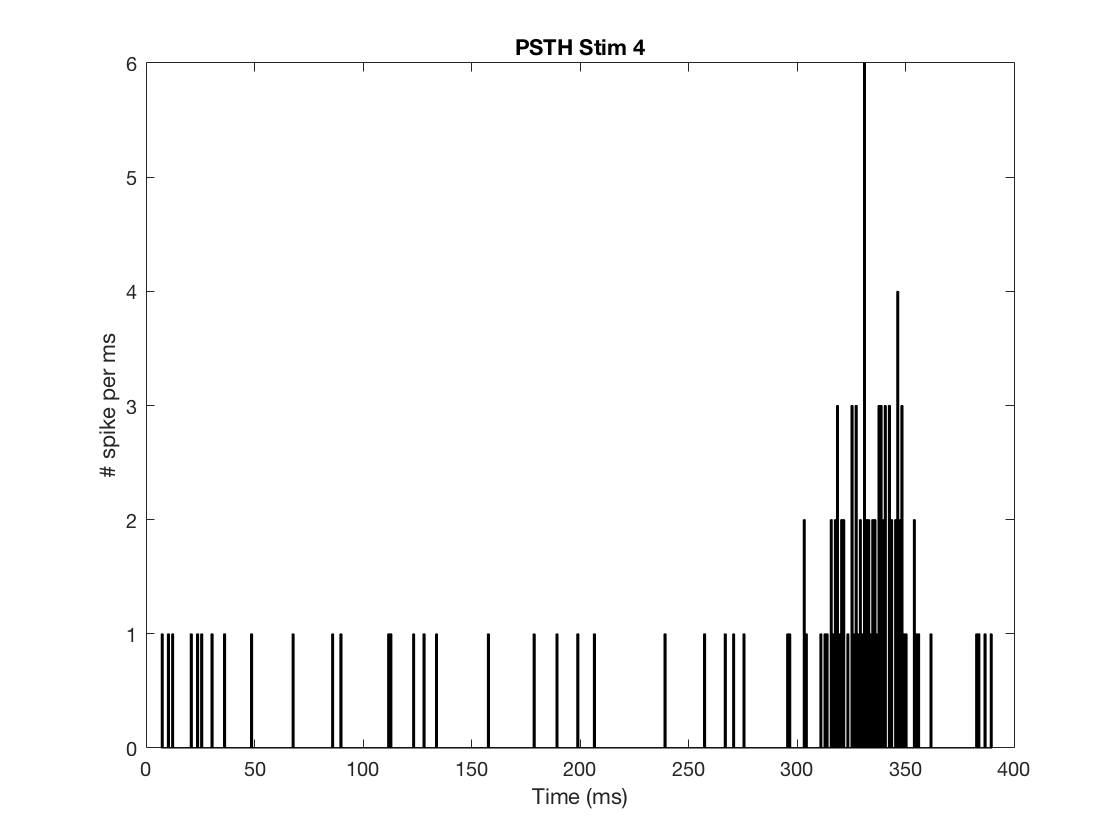

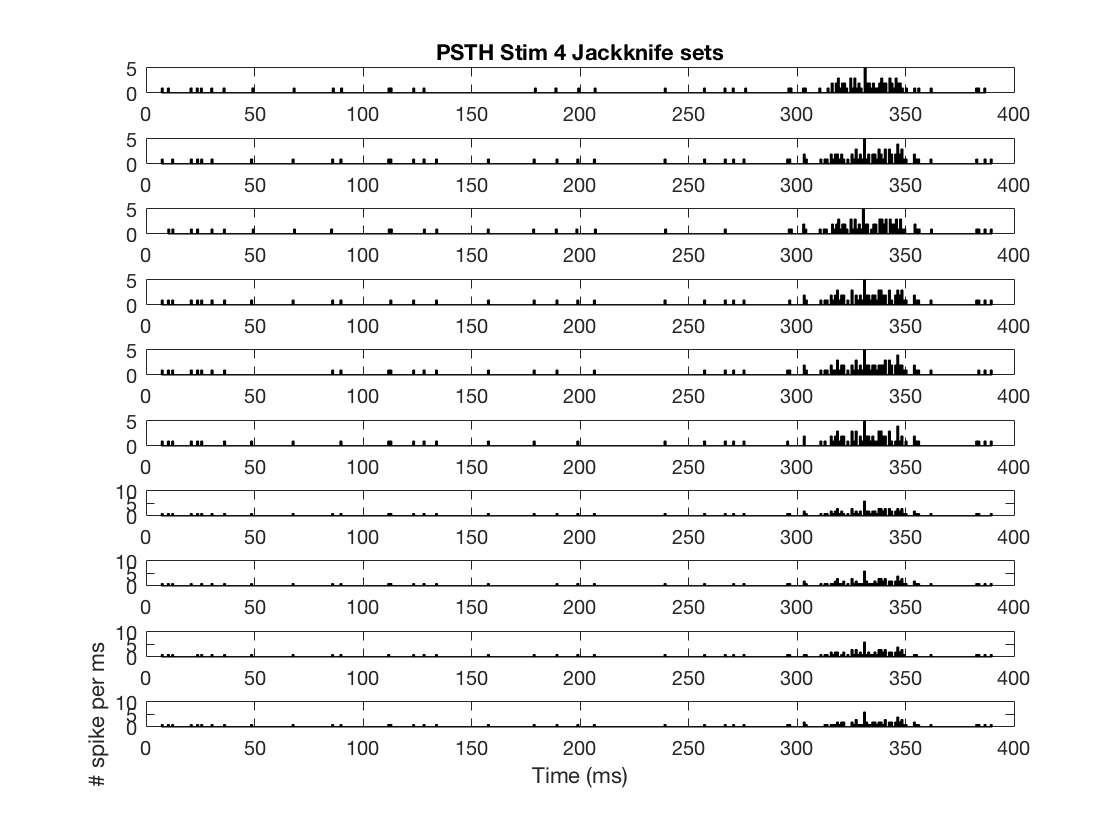

% Some plots of the spike arrival times
DataCell=load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));

for stim=1:DataCell.NStims
    % Plot the histogram of spike arrival times for that stim
    figure;
    hist(DataCell.Spike_arrival.(sprintf('stim%d',stim)), DataCell.NR_Duration)
    h=findobj(gca, 'Type', 'patch');
    h.FaceColor = 'k';
    h.EdgeColor = 'k';
    xlabel('Time (ms)')
    ylabel('# spike per ms')
    title(sprintf('PSTH Stim %d',stim));
    % Plot the histogram of spike arrival times for all the JK of that stim
    F=figure;
    for tt=1:NTrials
        subplot(NTrials,1,tt)
        hist(DataCell.JK_Spike_arrival.(sprintf('stim%d',stim)){tt}, DataCell.NR_Duration)
        xlim([0 400])
        h=findobj(gca, 'Type', 'patch');
        h.FaceColor = 'k';
        h.EdgeColor = 'k';
    end
    xlabel('Time (ms)')
    ylabel('# spike per ms')
    subplot(NTrials,1,1)
    F.Children(10).Title.String = sprintf('PSTH Stim %d Jackknife sets',stim);
end

## 2. Calculating Kernel density estimates of time varying spike rates

Calculating the Kernel Density Estimate of the spike trains of each stim and for each Jackknife set using the code from Hideaki Shimazaki and Shigeru Shinomoto (ssvkernel.m)

Kernel Bandwidth Optimization in Spike Rate Estimation. Journal of Computational Neuroscience 2010. [http://dx.doi.org/10.1007/s10827-009-0180-4](http://dx.doi.org/10.1007/s10827-009-0180-4)

DataCell = load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));

DataCell.Spike_filtered = struct(); % contains the KDE of the spike rate for each stim (one response vector per stimulus)
DataCell.JK_Spike_filtered = struct(); % contains NTrials Jackknife KDE of the spike rate for each stim (one (NTrials) * (response duration) matrix per stimulus)
Sum2Error = zeros(DataCell.NStims,1); % contains the SSE of the spike rate KDE compared to ground truth

% Set the time points at which the estimate should be calculated
DataCell.tin = 1/2:1:DataCell.NR_Duration;

for stim=1:DataCell.NStims
    % Calculating kernel density estimation of neural response
    [y,t,~,~,~,~,~] = ssvkernel(DataCell.Spike_arrival.(sprintf('stim%d',stim)),DataCell.tin);
    if sum(DataCell.tin==t)~=length(DataCell.tin)
        sprintf('WARNING KDE of stim %d is not calculated using the expected tin', stim);
    end
    % y is a density function that sums to 1
    % multiplying by the total number of spikes gives the number of expecting spike per time bin (here 1 ms) for all 10 Trials
    % dividing by the number of trials give the expected number of spikes per time bin for a trial
    DataCell.Spike_filtered.(sprintf('stim%d',stim)) =  y* DataCell.NSpikes.(sprintf('stim%d',stim))/DataCell.NTrials;
        
    % Calculating Kernel density estimation for JK spike trains
    DataCell.JK_Spike_filtered.(sprintf('stim%d',stim)) = nan(DataCell.NTrials, DataCell.NR_Duration);
    for tt=1:DataCell.NTrials
        [y,t,~,~,~,~,~] = ssvkernel(DataCell.JK_Spike_arrival.(sprintf('stim%d',stim)){tt},DataCell.tin);
        if sum(DataCell.tin==t)~=length(DataCell.tin)
            sprintf('WARNING KDE of stim %d JK set %d is not calculated using the expected tin', stim, tt);
        end
        DataCell.JK_Spike_filtered.(sprintf('stim%d',stim))(tt,:) =  y* DataCell.JK_NSpikes.(sprintf('stim%d',stim))(tt)/(DataCell.NTrials-1);
    end
    
    % Calculate the error with ground truth
    Win_old = 1;
    for ww = 1:length(DataCell.Win)
        Win_local = DataCell.Win(ww);
        Sum2Error(stim) = Sum2Error(stim) + sum((DataCell.Spike_filtered.(sprintf('stim%d',stim))(Win_old:Win_local) - ones(1,DataCell.Step).*DataCell.Input_Spike_count(stim,ww)./DataCell.Step).^2);
        Win_old = Win_local+1;
    end
end

computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done


computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization comp

computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done


computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization comp

computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done


computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization comp

computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done


computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization completed.
computing bootstrap confidence intervals...
done
computing local bandwidths...
adapting local bandwidths...
optimization comp

DataCell.SSE_KDE_SpikeRate = Sum2Error;
DataCell.MSE_KDE_SpikeRate = Sum2Error./NR_Duration;
DataCell.Average_MSE_KDE_SpikeRate = ((mean(DataCell.MSE_KDE_SpikeRate)).^0.5);
save(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)),'-struct','DataCell', '-append');   


Pot the estimated time varying spike rates along with the initial ground true rates.

Error bars on the spike rate estimation are given by the Jackkinfe procedure.

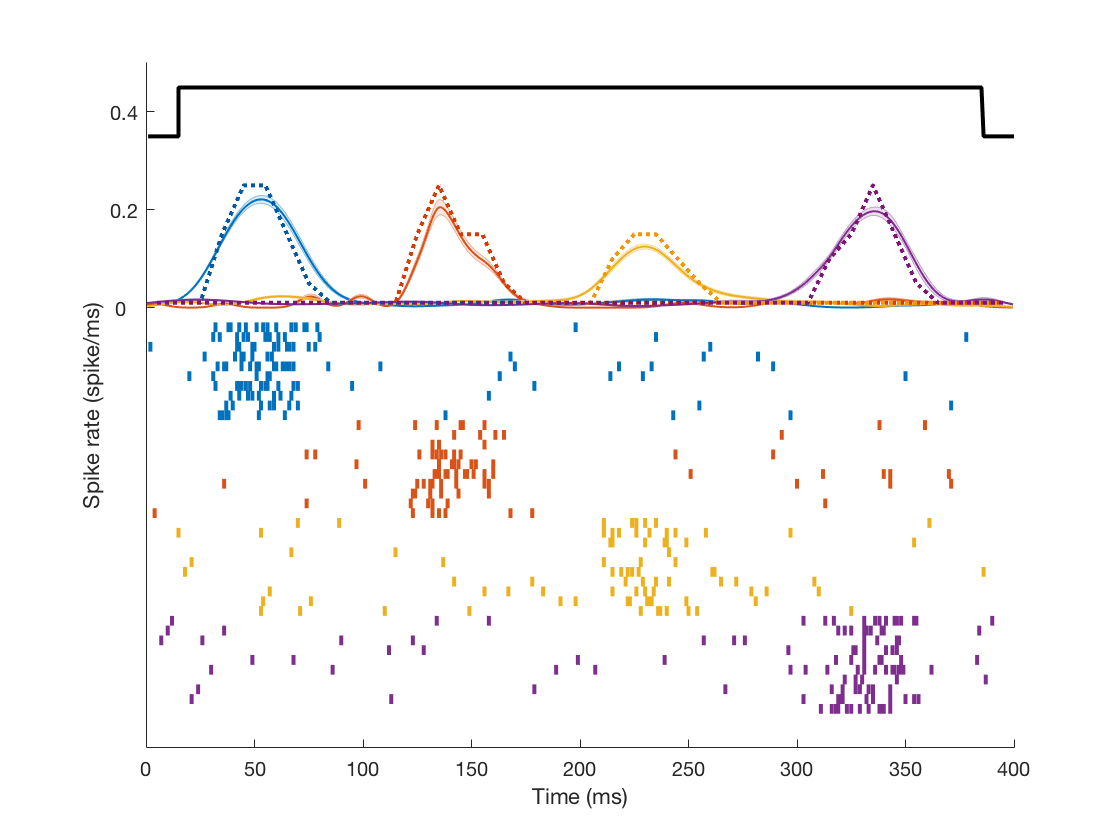

DataCell = load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));
close all

figure;
RGB_code = get(gca, 'ColorOrder');
% Plot the KDE of PSTH and JK error
cc=0;
for stim=1:DataCell.NStims
    shadedErrorBar(DataCell.tin,DataCell.Spike_filtered.(sprintf('stim%d',stim)), std(DataCell.JK_Spike_filtered.(sprintf('stim%d',stim)),1),{'Color',RGB_code(stim,:), 'LineStyle','-', 'LineWidth',1},1)
    hold on
    SA_local = DataCell.Spike_array.(sprintf('stim%d',stim));
    for tt=1:DataCell.NTrials
        Local_trial = find(SA_local(tt,:));
        for ss=1:length(Local_trial)
            hold on
            plot([Local_trial(ss) Local_trial(ss)], [-0.05-0.02*cc -0.03-0.02*cc], 'LineWidth', 2, 'Color', RGB_code(stim,:))
        end
        cc=cc+1;
    end    
end

% Plot the ground truth
for stim=1:DataCell.NStims
    hold on
    plot((1:40)*10-5, DataCell.Input_Spike_count(stim,:)./DataCell.Step, 'Color',RGB_code(stim,:) + [0 -0.1 -0.09], 'LineStyle',':', 'LineWidth',2)
end
hold on
Xsound = [1:15 15:(DataCell.NR_Duration-30) (DataCell.NR_Duration-30):DataCell.NR_Duration];
Ysound = DataCell.Step*[repmat(0.035,1,15) repmat(0.045, 1, DataCell.NR_Duration-28) repmat(0.035,1,15)];
plot(Xsound, Ysound, 'k', 'LineWidth',2)
set(gca,'YTick',[0 0.2 0.4],'YTickLabel',[0 0.2 0.4], 'Box', 'off')
xlabel('Time (ms)')
ylabel('Spike rate (spike/ms)')
ylim([-0.9 0.5])
hold off

fprintf('Average mean square errors for the rate over stimuli:%.2f spike/ms\n', DataCell.Average_MSE_KDE_SpikeRate);

Average mean square errors for the rate over stimuli:0.02 spike/ms


## **3. Binning the Kernel density estmates of the time-varying rate and calculating the in**formation of the neural response about the stimulus at each time point

This section of code calculate the instantaneous information about the stimulus from:

-> the kernel density estimates of the time-varying spike rates (Info) assuming stochastic (inhomogenous Poisson) responses

-> the ground true rates assuming stochastic (inhomogenous Poisson) responses (Max_PoissInfo)

-> the Jackknife kernel density estimates of the time-varying spike rates assuming stochastic (inhomogenous Poisson) responses (Info_Boot_JK)¶

DataCell = load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));

% Initializing output variables
Nb_Boot = 100;
DataCell.Nb_Boot_inf = Nb_Boot;
NStims = DataCell.NStims;
NTrials = DataCell.NTrials;
Ymax = DataCell.Step*2;
Win = DataCell.Win;
Nb_Win = length(Win);
DataCell.SC_data = nan(NStims,length(Win));
DataCell.Bin_Trials = nan(NStims,NTrials,length(Win));
% output variables of the calculation of information on KDE rates
DataCell.Info = nan(1,Nb_Win);
DataCell.HY = nan(1,Nb_Win);
DataCell.HYS = nan(1,Nb_Win);
DataCell.P_YgivenS = cell(1,Nb_Win);
% output variables of the calculation of information on ground true rate assuming stochastic (inhomogenous Poisson) responses
DataCell.Max_PoissInfo = nan(1,Nb_Win);% This is the max total info that you can expect if the neural response was noisy (H(Y/S)~=0) and you knew exactly the spike rate
DataCell.HY_Theo = nan(1,Nb_Win);
DataCell.HYS_Theo = nan(1,Nb_Win);
DataCell.P_YgivenS_Theo = cell(1,Nb_Win);
% output variables of the calculation of information on the jackknife sets of KDE rates
DataCell.Info_Boot_JK = cell(Nb_Boot,1);
DataCell.HY_Boot_JK = cell(Nb_Boot,1);
DataCell.HYS_Boot_JK = cell(Nb_Boot,1);
DataCell.P_YgivenS_BootJK = cell(Nb_Boot,1);

% Summary statistics for the jackknife procedure
DataCell.Info_BootJK_mean = nan(Nb_Boot,Nb_Win);
DataCell.Info_BootJK_var = nan(Nb_Boot,Nb_Win);
DataCell.Info_BootJK_inf = cell(Nb_Boot,1);
DataCell.Info_BootJK_inf_mean = nan(Nb_Boot,Nb_Win);
DataCell.Info_BootJK_inf_var = nan(Nb_Boot,Nb_Win);
DataCell.HY_BootJK_inf = cell(Nb_Boot,1);
DataCell.HY_BootJK_inf_mean = nan(Nb_Boot,Nb_Win);
DataCell.HY_BootJK_inf_var = nan(Nb_Boot,Nb_Win);
DataCell.HYS_BootJK_inf = cell(Nb_Boot,1);
DataCell.HYS_BootJK_inf_mean = nan(Nb_Boot,Nb_Win);
DataCell.HYS_BootJK_inf_var = nan(Nb_Boot,Nb_Win);


Win_old=1;
for  ww=1:Nb_Win
    Win_local=Win(ww)*DataCell.Response_samprate/1000;
    % First calculating info for the actual dataset
    % getting mean spike count ready
    for stim=1:NStims
        DataCell.SC_data(stim,ww) = sum(DataCell.Spike_filtered.(sprintf('stim%d',stim))(Win_old:Win_local));
    end
    
    % Calculating instantaneous information on Kernel density estimates of the time-varying rates assuming stochastic (inhomogenous Poisson) responses
    fprintf(1,'Calculating info for time point %d/%d\n',ww,Nb_Win);
    [DataCell.Info(ww),DataCell.P_YgivenS{ww},DataCell.HY(ww), DataCell.HYS(ww)] = info_poisson_model_calculus(DataCell.SC_data(:,ww), 'Ymax', Ymax);
    
    % Calculating instantaneous information on the ground true rate assuming stochastic (inhomogenous Poisson) responses
    [DataCell.Max_PoissInfo(ww),DataCell.P_YgivenS_Theo{ww},DataCell.HY_Theo(ww), DataCell.HYS_Theo(ww)] = info_poisson_model_calculus(DataCell.Input_Spike_count(:,ww), 'Ymax', Ymax);
    
    % Incrementing old window ref
    Win_old = Win_local+1;
end

Calculating info for time point 1/40
Calculating info for time point 2/40
Calculating info for time point 3/40
Calculating info for time point 4/40
Calculating info for time point 5/40
Calculating info for time point 6/40
Calculating info for time point 7/40
Calculating info for time point 8/40
Calculating info for time point 9/40
Calculating info for time point 10/40
Calculating info for time point 11/40
Calculating info for time point 12/40
Calculating info for time point 13/40
Calculating info for time point 14/40
Calculating info for time point 15/40
Calculating info for time point 16/40
Calculating info for time point 17/40
Calculating info for time point 18/40
Calculating info for time point 19/40
Calculating info for time point 20/40
Calculating info for time point 21/40
Calculating info for time point 22/40
Calculating info for time point 23/40
Calculating info for time point 24/40
Calculating info for time point 25/40
Calculating info for time point 26/40
Calculating info for 


% Now bootstraping the calculation for the KDE rates
% on JK spike patterns
SetIndices_JK = cell(Nb_Boot,1);
parfor bb=1:Nb_Boot
    LocalSet = nan(NTrials, NStims);
    for vv=1:NStims
        LocalSet(:,vv) = randperm(NTrials,NTrials);
    end
    SetIndices_JK{bb} = LocalSet;
end

% Loop through the bootstraps
for bb=1:Nb_Boot
    DataCell.Info_Boot_JK{bb} = nan(NTrials,Nb_Win);
    DataCell.P_YgivenS_BootJK{bb} = cell(NTrials,Nb_Win);
    DataCell.HY_Boot_JK{bb} = nan(NTrials,Nb_Win);
    DataCell.HYS_Boot_JK{bb} = nan(NTrials,Nb_Win);
    % Loop through the sets of JK points for that bootstrap
    for jk=1:NTrials
        Spike_Filtered_Boot = nan(NStims,DataCell.NR_Duration*DataCell.Response_samprate/1000);
        for stim=1:NStims
            Spike_Filtered_Boot(stim,:) = DataCell.JK_Spike_filtered.(sprintf('stim%d',stim))(SetIndices_JK{bb}(jk,stim),:);
        end
        Win_old=1;
        for  ww=1:Nb_Win
            Win_local=Win(ww)*DataCell.Response_samprate/1000;
            [DataCell.Info_Boot_JK{bb}(jk,ww),DataCell.P_YgivenS_BootJK{bb}{jk,ww},DataCell.HY_Boot_JK{bb}(jk,ww),DataCell.HYS_Boot_JK{bb}(jk,ww)] = info_poisson_model_calculus(sum(Spike_Filtered_Boot(:,Win_old:Win_local),2), 'Ymax', Ymax);
            % Incrementing old window ref
            Win_old = Win_local+1;
        end
    end
    DataCell.Info_BootJK_mean(bb,:) = mean(DataCell.Info_Boot_JK{bb},1);
    DataCell.Info_BootJK_var(bb,:) = var(DataCell.Info_Boot_JK{bb},0,1);
    % Calculating information and entropies for an infinite number of trials
    DataCell.Info_BootJK_inf{bb} = NTrials * repmat(DataCell.Info,NTrials,1) - (NTrials-1) * DataCell.Info_Boot_JK{bb};
    DataCell.Info_BootJK_inf_mean(bb,:) = mean(DataCell.Info_BootJK_inf{bb},1);
    DataCell.Info_BootJK_inf_var(bb,:) = var(DataCell.Info_BootJK_inf{bb},0,1);
    DataCell.HY_BootJK_inf{bb} = NTrials * repmat(DataCell.HY,NTrials,1) - (NTrials-1) * DataCell.HY_Boot_JK{bb};
    DataCell.HY_BootJK_inf_mean(bb,:) = mean(DataCell.HY_BootJK_inf{bb},1);
    DataCell.HY_BootJK_inf_var(bb,:) = var(DataCell.HY_BootJK_inf{bb},0,1);
    DataCell.HYS_BootJK_inf{bb} = NTrials * repmat(DataCell.HYS,NTrials,1) - (NTrials-1) * DataCell.HYS_Boot_JK{bb};
    DataCell.HYS_BootJK_inf_mean(bb,:) = mean(DataCell.HYS_BootJK_inf{bb},1);
    DataCell.HYS_BootJK_inf_var(bb,:) = var(DataCell.HYS_BootJK_inf{bb},0,1);
end
DataCell.Info_bcorr = mean(DataCell.Info_BootJK_inf_mean,1);
DataCell.Info_err = (mean(DataCell.Info_BootJK_inf_var,1)).^0.5;
save(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)),'-struct','DataCell','-append');

Now plot the results of the calculations of instantaneous information about the 4 stimuli

First, Instantaneous Information on ground-true rate assuming stochastic responses (Poisson)

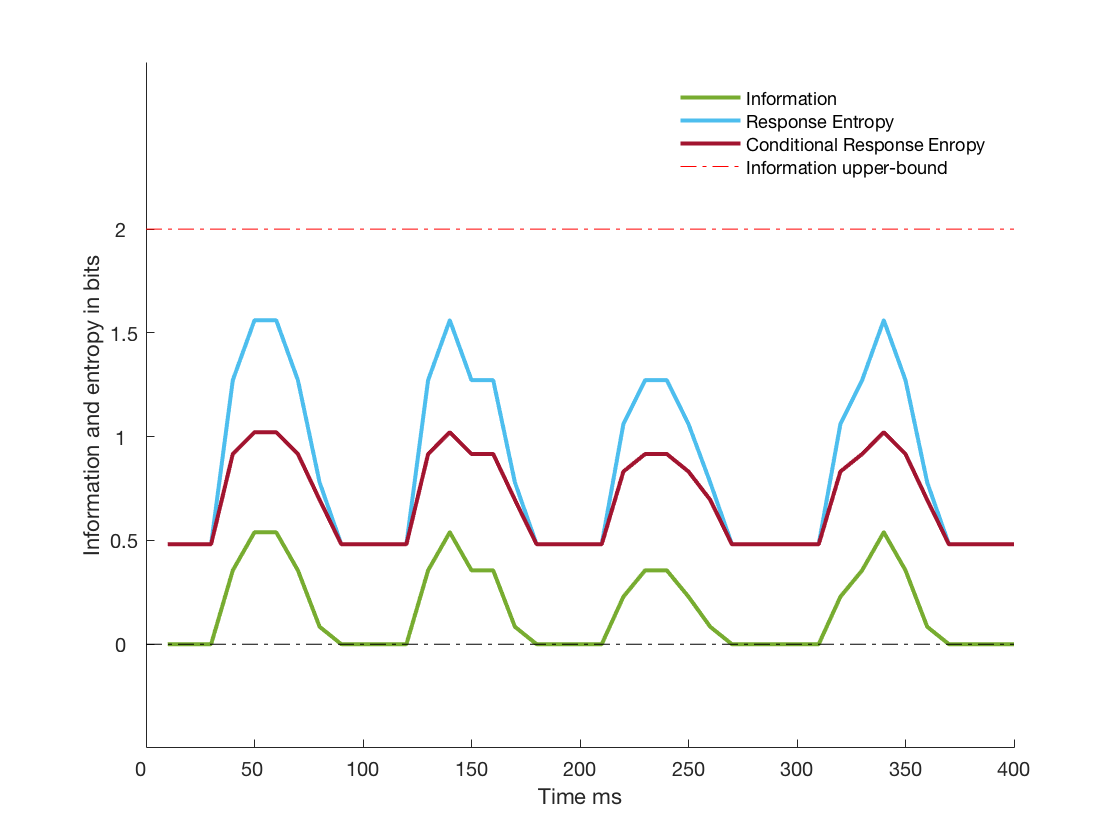

DataCell = load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));
figure;
ColorCode = get(groot,'DefaultAxesColorOrder');
ColorCode = [ColorCode ; 0.85 0.6940 0.556; 0.301 0.078 0.556; 0.929 0.184 0.188; 0.494 0.6740 0.933;0.466 0.745 0.184;0.635 0.694 0.7410];
Nb_Win = length(DataCell.Win);

% Plotting instantaneous information and entropy values calculated on the ground true rate assuming these are stochastic responses
plot(1:Nb_Win,DataCell.Max_PoissInfo,'LineWidth',2, 'Color',ColorCode(5,:))
hold on
plot(1:Nb_Win,DataCell.HY_Theo,'LineWidth',2, 'Color',ColorCode(6,:))
hold on
plot(1:Nb_Win,DataCell.HYS_Theo, 'LineWidth',2, 'Color',ColorCode(7,:))
hold on
line([0 Nb_Win], [log2(DataCell.NStims) log2(DataCell.NStims)], 'LineStyle','-.','Color','r')
legend('Information', 'Response Entropy','Conditional Response Enropy','Information upper-bound', 'Location','NorthEast');
legend boxoff
legend('AutoUpdate', 'off')
hold on
line([0 Nb_Win], [0 0], 'LineStyle','-.','Color','k')
hold off
ylim([-0.5 log2(DataCell.NStims)+0.8])
Xtickposition=get(gca,'XTick');
set(gca,'XTickLabel', Xtickposition*DataCell.Step, 'Box', 'off', 'YTick', [0 0.5 1 1.5 2],'YTickLabel', [0 0.5 1 1.5 2])
xlabel('Time ms')
ylabel('Information and entropy in bits')

Then, Instantaneaous Information on Kernel Density Estimated (KDE) rates assuming stochastic responses (Poisson)

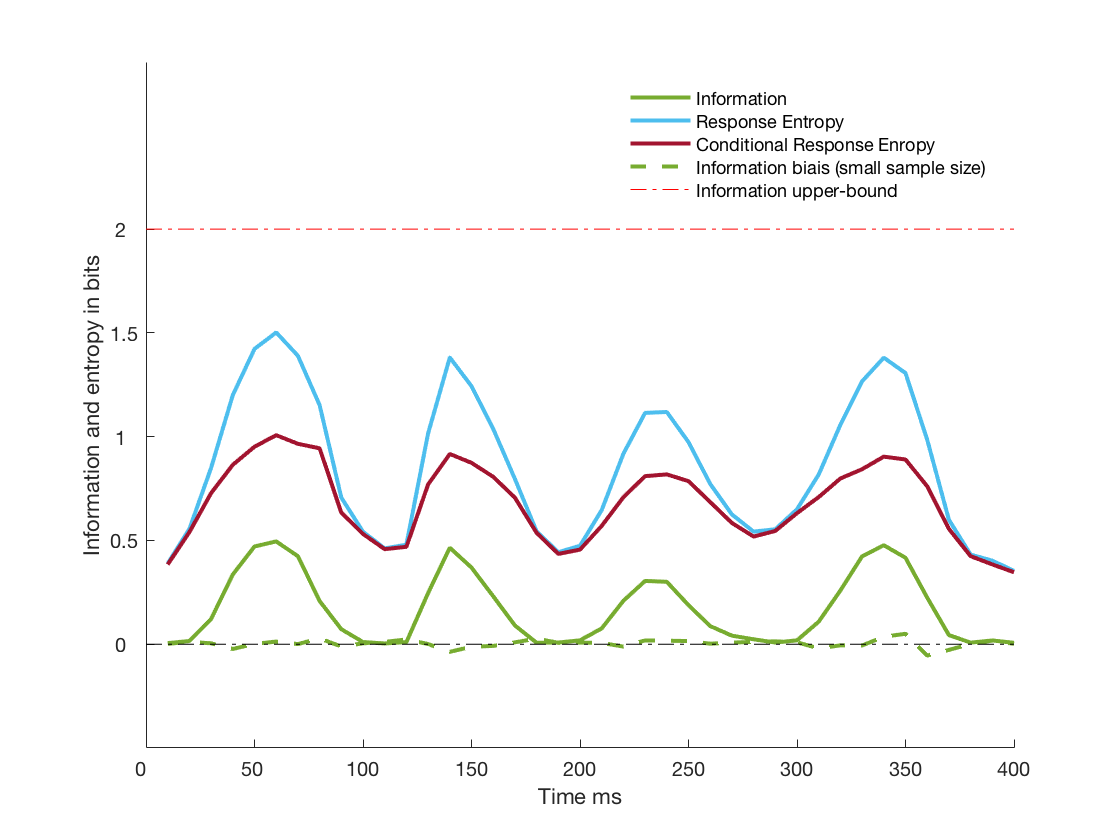

figure;
ColorCode = get(groot,'DefaultAxesColorOrder');
ColorCode = [ColorCode ; 0.85 0.6940 0.556; 0.301 0.078 0.556; 0.929 0.184 0.188; 0.494 0.6740 0.933;0.466 0.745 0.184;0.635 0.694 0.7410];
Nb_Win = length(DataCell.Win);

% Plotting instantaneous information and entropy calculated on the KDE rates
plot(1:Nb_Win,DataCell.Info,'LineWidth',2, 'Color',ColorCode(5,:))
hold on
plot(1:Nb_Win,DataCell.HY,'LineWidth',2, 'Color',ColorCode(6,:))
hold on
plot(1:Nb_Win,DataCell.HYS, 'LineWidth',2, 'Color',ColorCode(7,:))
hold on
plot(1:Nb_Win,DataCell.Info - DataCell.Info_bcorr,'LineWidth',2, 'Color',[ColorCode(5,:) 0.5],'LineStyle','--')
hold on
line([0 Nb_Win], [log2(DataCell.NStims) log2(DataCell.NStims)], 'LineStyle','-.','Color','r')
legend('Information', 'Response Entropy','Conditional Response Enropy','Information biais (small sample size)','Information upper-bound', 'Location','NorthEast');
legend boxoff
legend('AutoUpdate', 'off')
hold on
line([0 Nb_Win], [0 0], 'LineStyle','-.','Color','k')
hold off
ylim([-0.5 log2(DataCell.NStims)+0.8])
Xtickposition=get(gca,'XTick');
set(gca,'XTickLabel', Xtickposition*DataCell.Step, 'Box', 'off', 'YTick', [0 0.5 1 1.5 2],'YTickLabel', [0 0.5 1 1.5 2])
xlabel('Time ms')
ylabel('Information and entropy in bits')

Finally here is the instantaneous time varying information with its jackknife estimated error.

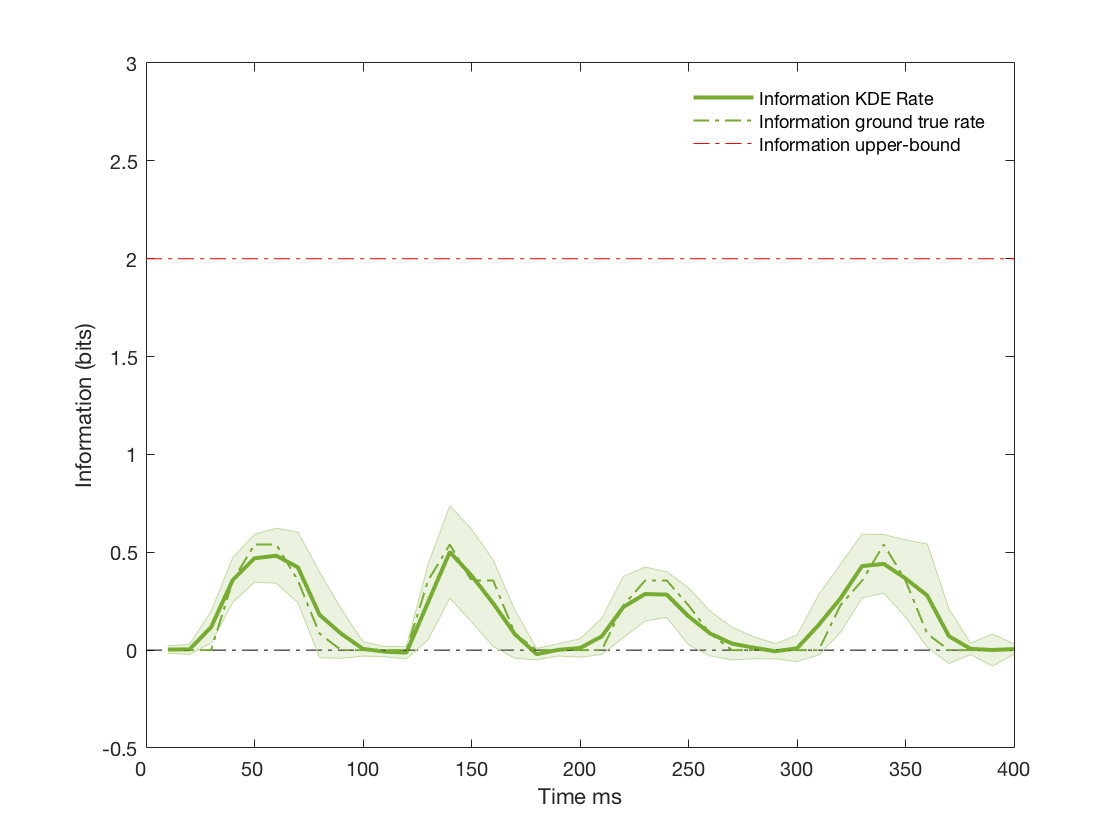

% Plotting instantaneous information data and its error
plot(1:Nb_Win,DataCell.Info_bcorr,'LineWidth',2, 'Color',ColorCode(5,:))
hold on
plot(1:Nb_Win,DataCell.Max_PoissInfo,'LineWidth',1, 'LineStyle','-.','Color',ColorCode(5,:));
hold on
line([0 Nb_Win], [log2(DataCell.NStims) log2(DataCell.NStims)], 'LineStyle','-.','Color','r')
legend('Information KDE Rate','Information ground true rate','Information upper-bound', 'Location','NorthEast');
legend boxoff
legend('AutoUpdate', 'off')
hold on
line([0 Nb_Win], [0 0], 'LineStyle','-.','Color','k')
hold on
ylim([-0.5 log2(DataCell.NStims)+1])
Xtickposition=get(gca,'XTick');
set(gca,'XTickLabel', Xtickposition*DataCell.Step)
xlabel('Time ms')
ylabel('Information (bits)')
shadedErrorBar([],DataCell.Info_bcorr, DataCell.Info_err,{'Color',ColorCode(5,:), 'LineStyle','-', 'LineWidth',1},1)
hold on
plot(1:Nb_Win,DataCell.Max_PoissInfo,'LineWidth',1, 'LineStyle','-.','Color',ColorCode(5,:));%,[0.8 0.5 0.3])
hold off

## 4. Calculating the cumulative information using a Monte Carlo with importance sampling approach

The error is estiamted by a bootrstrap on top of a Jackknife procedure.

Cum_boot=10; % Here we are bootstraping the calculations only 10 times as these calculations are really costly in computation time
Data=load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));
P_YgivenS = Data.P_YgivenS;
P_YgivenS_BootJK = Data.P_YgivenS_BootJK;
Bin_Trials = Data.Bin_Trials;
clear Data

%% Calculate the Monte Carlo estimation
MaxMCParameter = 5*10^6; % This is the maximum number of samples for the MC to calculate an estimate
ConvThresh = 0.2; % The number of samples is progressively increased to the max value MaxMCParameter unless the error on the estimate is lower than 3 times 0.2bits, indicating convergence
IncrMCParameter = 10^5; % step by which the number of MC samples is increased for a given estimation of information value
NTrials = size(Bin_Trials,2);
clear Bin_Trials
Nb_Win = length(P_YgivenS);
Icum_EstMonteCarloOpt = nan(1,Nb_Win);
Icum_EstMonteCarloOpt_err = nan(1,Nb_Win);
Icum_EstMonteCarloOpt_bcorr = nan(1,Nb_Win);
MC_Samp = nan(1,Nb_Win);
tstart2 = tic;
Error_local = 0;
tt=1;
while ((Error_local<=(3*ConvThresh)) && (tt<Nb_Win))
    tt= tt+1;
    tstart = tic;
    fprintf('Time point %d/%d\n', tt, Nb_Win);
    P_YgivenS_local = P_YgivenS(1:tt);
    P_YgivenS_JK_local = cell(1:Cum_boot);
    for bb=1:Cum_boot
        P_YgivenS_JK_local{bb} = P_YgivenS_BootJK{bb}(:,1:tt);
    end
    
    % Monte Carlo estimation
    [Icum_EstMonteCarloOpt(tt),~, ~, Icum_EstMonteCarloOpt_bcorr(tt),Icum_EstMonteCarloOpt_err(tt),MC_Samp(tt)]=cumulative_info_poisson_model_calculus_MCJK(P_YgivenS_local, P_YgivenS_JK_local,NTrials,'ConvThresh',ConvThresh, 'MaxMCParameter',MaxMCParameter, 'IncrMCParameter', IncrMCParameter);
    fprintf('# MC samples %d Error:%.2f\n', MC_Samp(tt),Icum_EstMonteCarloOpt_err(tt));
    telapsed = toc(tstart);
    fprintf('Elapsed time: %d s\n', telapsed)
    Error_local=Icum_EstMonteCarloOpt_err(tt);
end

Time point 2/40


# MC samples 100000 Error:0.04


Elapsed time: 3.634922e+01 s


Time point 3/40


# MC samples 100000 Error:0.09


Elapsed time: 4.806523e+01 s


Time point 4/40


fprintf('Calculations stop at %d with an error of: %.2f\n', tt, Icum_EstMonteCarloOpt_err(tt))
telapsed2 = toc(tstart2);
fprintf('MC with importance sampling total elapsed time: %d s\n', telapsed2)

load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)),'Info_bcorr');
Icum_EstMonteCarloOpt(1) = Info_bcorr(1); % Initializing the first value of cumulative info
Icum_EstMonteCarloOpt_bcorr(1) = Info_bcorr(1); % Initializing the first value of cumulative info
save(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)),'Nb_Win','Cum_boot','Icum_EstMonteCarloOpt','Icum_EstMonteCarloOpt_bcorr','Icum_EstMonteCarloOpt_err','MC_Samp','-append');
clear P_Y* Icum*

Now plot the results of the calculations of the cumulative information about the 4 stimuli

% load data
DataCell = load(fullfile(Path2Data, sprintf('%s_InfoCumInfo_Tutorial.mat',Cell)));
NTrials = size(DataCell.Bin_Trials,2);
Nb_Win = size(DataCell.Bin_Trials,3);
NStims = size(DataCell.Bin_Trials,1);
Step=10;

figure;
ColorCode = get(groot,'DefaultAxesColorOrder');
ColorCode = [ColorCode ; 0.85 0.6940 0.556; 0.301 0.078 0.556; 0.929 0.184 0.188; 0.494 0.6740 0.933;0.466 0.745 0.184;0.635 0.694 0.7410];
plot(1:Nb_Win,Info_bcorr,'LineWidth',2, 'Color',ColorCode(5,:))
hold on
plot(1:Nb_Win, Icum_EstMonteCarloOpt_bcorr, 'LineWidth',2, 'Color',ColorCode(1,:))
hold on
line([0 Nb_Win], [log2(NStims) log2(NStims)], 'LineStyle','-.','Color','r', 'LineWidth',2)
legend('Information','Cumulative Information', 'Location','NorthEast');
legend boxoff
legend('AutoUpdate','off')
hold on
line([0 Nb_Win], [0 0], 'LineStyle','-.','Color','k','LineWidth',2)
hold on
ylim([-0.5 log2(NStims)+2])
Xtickposition=get(gca,'XTick');
set(gca,'XTickLabel', Xtickposition*Step,'YTick',0:0.5:4,'YTickLabel',0:0.5:4)
xlabel('Time (ms)','FontWeight','bold','FontSize',12)
ylabel('Information (bits)','FontWeight','bold','FontSize',12)
shadedErrorBar([],Info_bcorr, Info_err,{'Color',ColorCode(5,:), 'LineStyle','-', 'LineWidth',2},1)
hold on
shadedErrorBar([],Icum_EstMonteCarloOpt_bcorr, Icum_EstMonteCarloOpt_err,{'Color',ColorCode(1,:), 'LineStyle','-', 'LineWidth',2},1)
hold off